n1 = 0:100;
N = 1000;
x = (2/5).*cos(((4*pi)/N)*n1) +(4/5).*sin(((6*pi)/N)*n1);

%Periodo
% X = fft(x,N)
% 
% %Frequencias 
% freq = (0:N-1)*(1/N)
% L = length(X)
% mdc = gcd(1:L-1, circshift(1:L-1, 1))
% periodo = L / mdc(end)
% 
% stem(freq, abs(X));

% n = 0:2000;
% N = 1000;
% x = (2/5).*cos(((4*pi)/N)*n) + (4/5).*sin(((6*pi)/N)*n);
% L = length(X)
% mdc = gcd(1:L-1, circshift(1:L-1, 1))
% periodo = L / mdc(end)
% X = fft(x,N)
% 
% stem(n, x);
% stem(freq, abs(X));

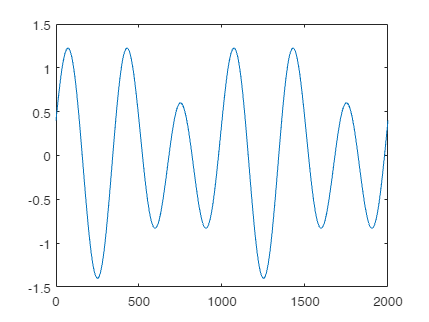

N = 1000;
funcao = @(n)(2/5*cos((4*pi/N)*n)+sin((6*pi/N)*n));
n = 0:2000;
x = funcao(n);
plot(n,x)

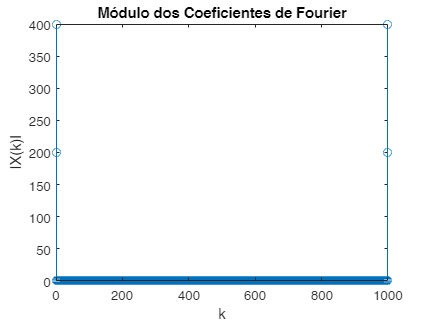

N = 1000; % Tamanho da DFT
n = 0:999; % Índices do sinal

% Sinal
x = (2/5).*cos(((4*pi)/N)*n) + (4/5).*sin(((6*pi)/N)*n);

% Calculando a DFT
ak = fft(x);

% Calculando o módulo dos coeficientes de Fourier
modulo_coef = abs(ak);

% Índices k para o plot
k = 0:N-1;

% Plotando o gráfico
figure;
stem(k, modulo_coef);
xlabel('k');
ylabel('|X(k)|');
title('Módulo dos Coeficientes de Fourier');

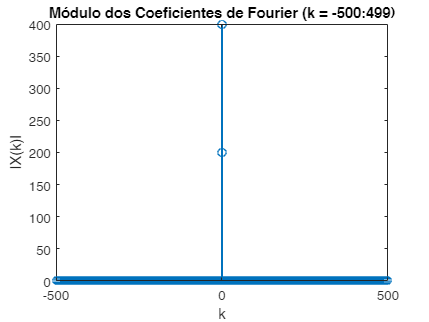

% Parâmetros
N = 1000; % Tamanho da DFT
n = 0:999; % Índices do sinal

% Sinal
x = (2/5).*cos(((4*pi)/N)*n) + (4/5).*sin(((6*pi)/N)*n);

% Calculando a DFT
X = fft(x);

% Aplicando fftshift para alinhar os coeficientes de Fourier
X_shifted = fftshift(X);

% Calculando o módulo dos coeficientes de Fourier
modulo_coeficientes = abs(X_shifted);

% Índices k para o plot
k = -500:499;

% Plotando o gráfico
figure;
stem(k, modulo_coeficientes);
xlabel('k');
ylabel('|X(k)|');
title('Módulo dos Coeficientes de Fourier (k = -500:499)');

n=0:300;
x1 =sin((2*pi)/100*n);
w0 = (2*pi)/100;
T = (2*pi)/w0

T = 100.0000

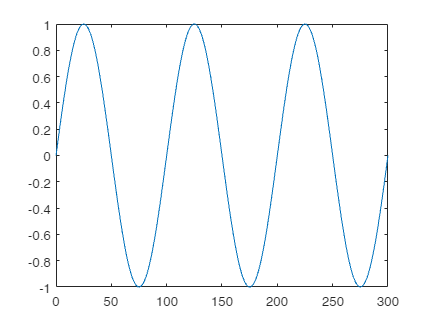

plot(n,x1)

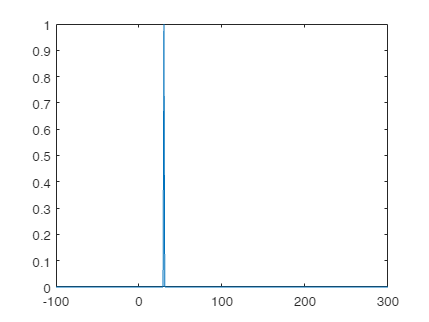

n=-100:300;
h=30;
n1 =h*k1; 
k1=1;
%x2 = sum(dirac(n1-50*k1));

x2_2 = @(n)(n - n1 == 0)*1 + (n-n1 < 0 & n-n1 > 0)*0;
plot(n,x2_2(n))

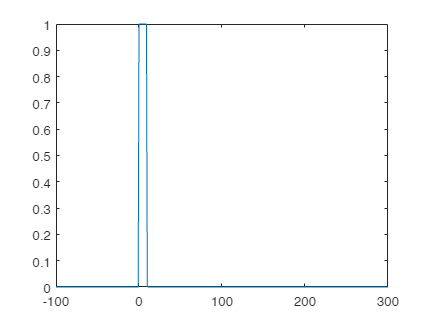

degrau=@(nn)(nn>=0)*1;
x3 = @(n)degrau(n)-degrau(n-n0);
plot(n,x3(n));

ak = fft(x1,50);
bk = fft(x2_2(n),50)

bk =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


ck = fft(x3(n),50)

ck =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x = (1/4).*(7+2.*cos((pi/2)*n)+3*cos(pi*n))

x =     3.0000    1.0000    2.0000    1.0000    3.0000    1.0000    2.0000    1.0000    3.0000    1.0000    2.0000    1.0000    3.0000    1.0000    2.0000    1.0000    3.0000    1.0000    2.0000    1.0000    3.0000    1.0000    2.0000    1.0000    3.0000    1.0000    2.0000    1.0000    3.0000    1.0000    2.0000    1.0000    3.0000    1.0000    2.0000    1.0000    3.0000    1.0000    2.0000    1.0000    3.0000    1.0000    2.0000    1.0000    3.0000    1.0000    2.0000    1.0000    3.0000    1.0000



P1 = 4

P1 = 4

P2 = 2

P2 = 2


fft(x,4)/4

ans =     1.7500    0.2500    0.7500    0.2500
